## **Step 7**

clear;
close all;

filename = 'gqrx_20221119_195628_904000000_2000000_fc.raw'; % Recording
Fs = 2000000;                                               % Sampling Rate
fid = fopen(filename, 'rb');                                % Opens the file
y = fread(fid, 'float');                                    % Reads the data and stores it in a variable 'y'
y = y(1:2:end) + 1i*y(2:2:end);                             % Constructs a complex vector from 'y'
fclose(fid);                                                % Closes the file
y = real(y);                                                % Discards the Q-Component (Imaginary Part) and retains the I-Component (Real Part)

## **Step 8**

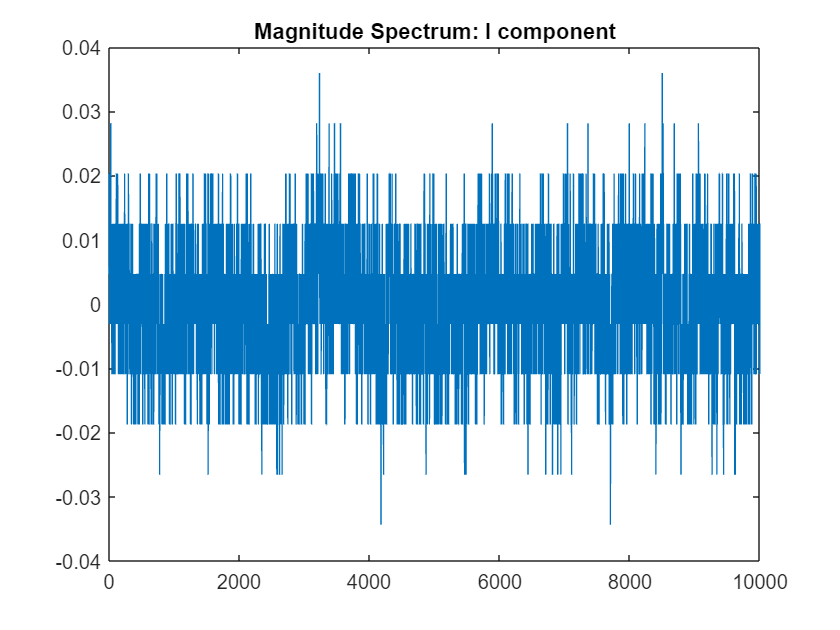

plot(y(1:10000))                         % The Y-Vector has a large number of samples, so plotting a small subset
title('Magnitude Spectrum: I component') % Sets the title for the plot

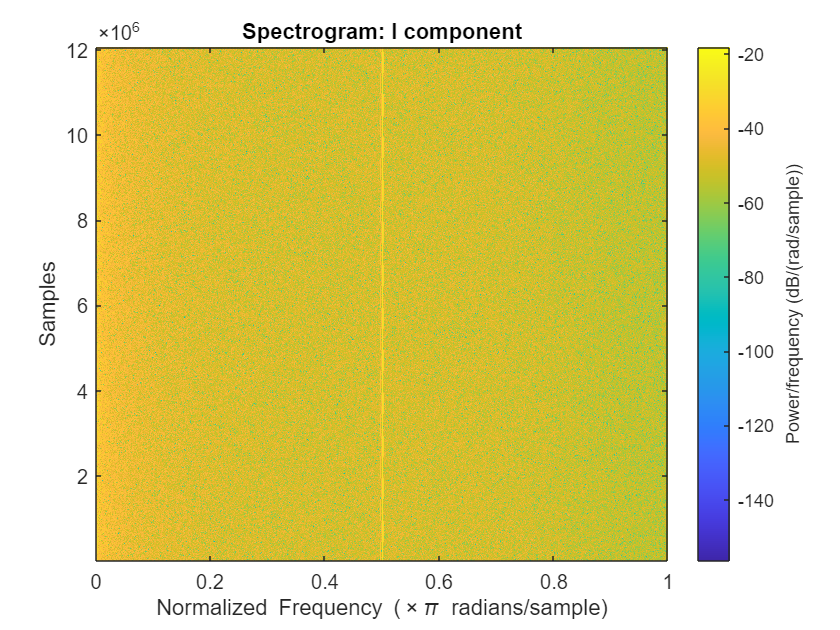

figure;                           % Creates a new figure window
spectrogram(y, 10000)             % Generates a spectrogram plot of y
title('Spectrogram: I component') % Sets the title for the plot

## **Step 11**

bpfilter = bpf;                       % Bandpass FIR Equiripple Filter built with Filter Designer
yR1 = sosfilt(bpfilter.sosMatrix, y); % Filter the signal with BPF
yR1 = yR1 / max(yR1);                 % Reduce the Amplitude

## **Step 12**

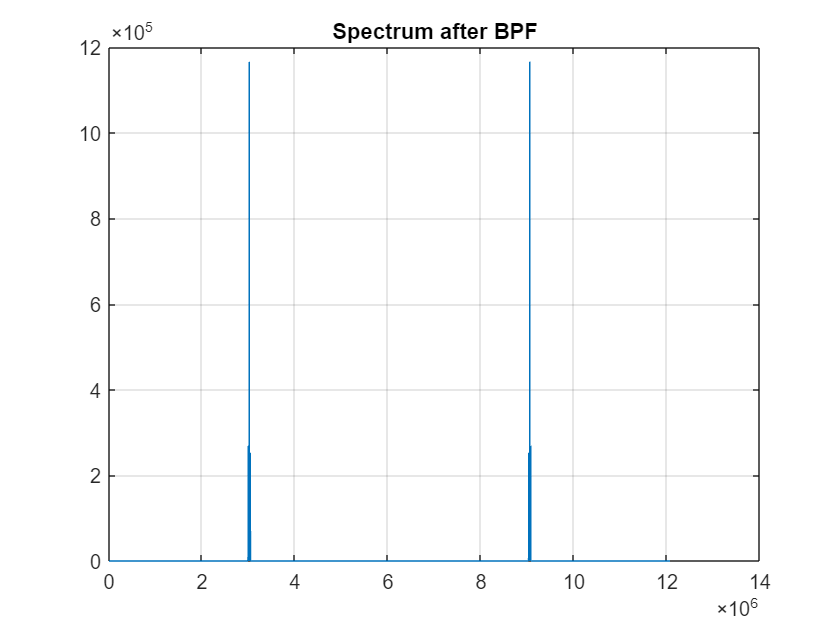

plot(abs(fft(yR1)))         % Plots the Magnitude Spectrum of the signal with FFT
title('Spectrum after BPF') % Sets the title for the plot
grid on;                    % Generates a plot with grid lines

## **Step 13**

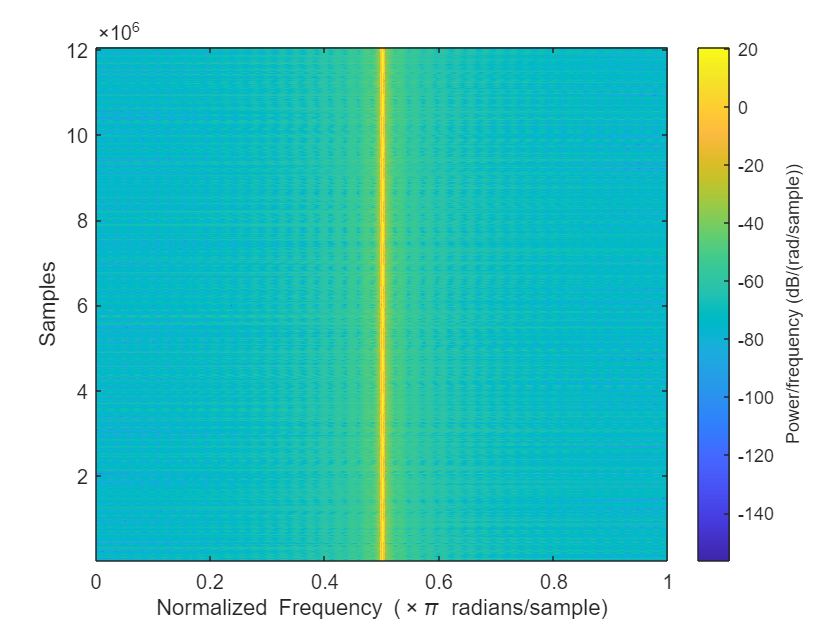

figure                  % Creates a new figure window
spectrogram(yR1, 10000) % Generates a spectrogram plot of yR1

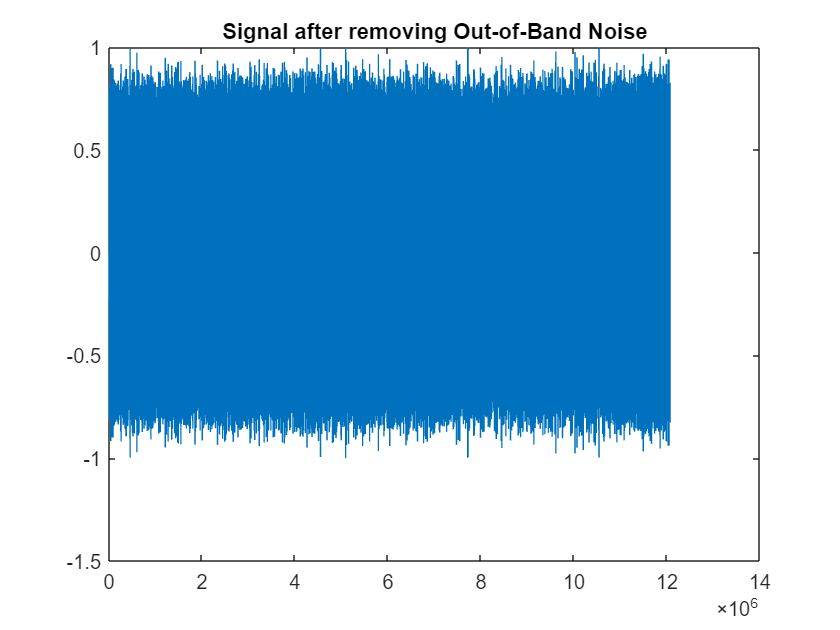

plot(yR1)                                        % Generates a plot of yR1
title('Signal after removing Out-of-Band Noise') % Sets the title for the plot

## **Step 14**

y_positive = abs(yR1(1:100:end)); % Positive Amplitudes. Reduce Sampling Rate by a factor of 10000

## **Step 15**

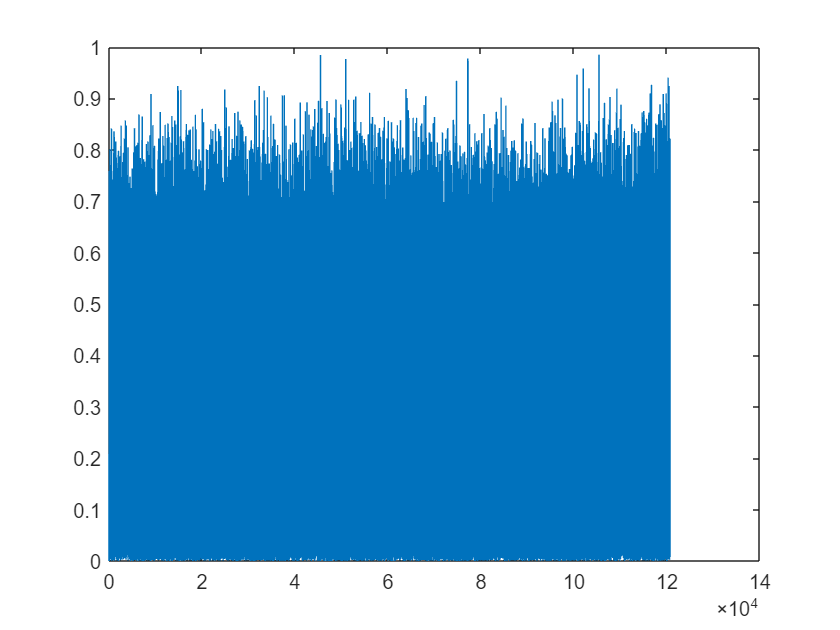

figure           % Creates a new figure window
plot(y_positive) % Generates a plot of y_positive

## **Step 17**

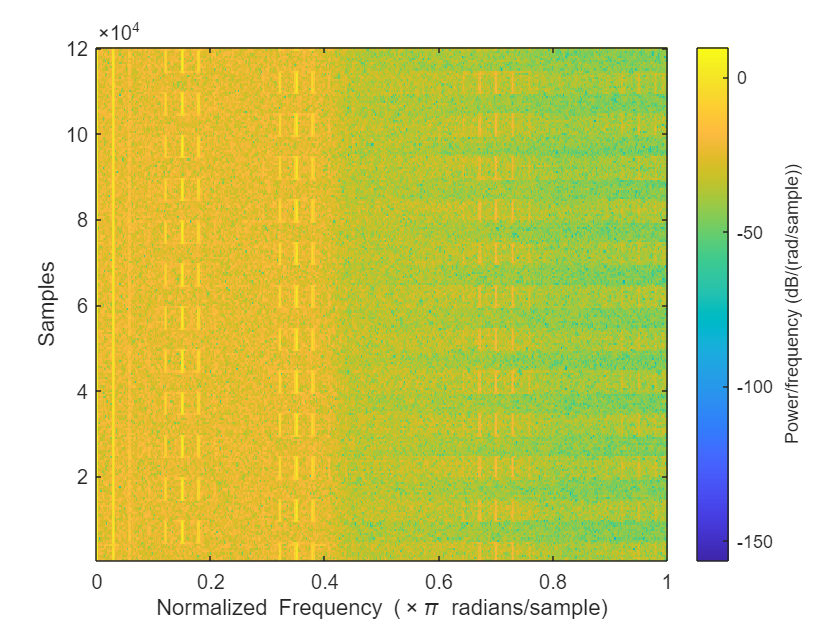

spectrogram(y_positive, 1000) % Generates a spectrogram plot of y_positive

## **Step 19**

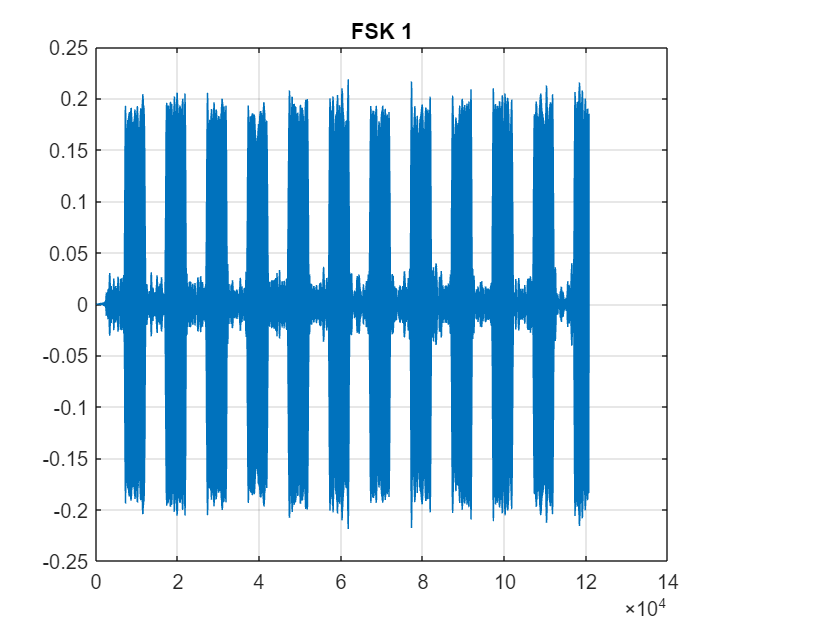

bpfilter = bpf1;                                    % BPF FIR Equiripple Filter built with Filter Designer
fsk1 = filter(bpfilter.Numerator, 1, (y_positive)); % Applying the BPF Filter to the signal
fsk1 = fsk1 / max(yR1);                             % Reduces the Amplitude
plot(fsk1)                                          % Generates a plot of fsk1
title('FSK 1')                                      % Sets the title for the plot
grid on;                                            % Generates a plot with grid lines

## **Step 20**

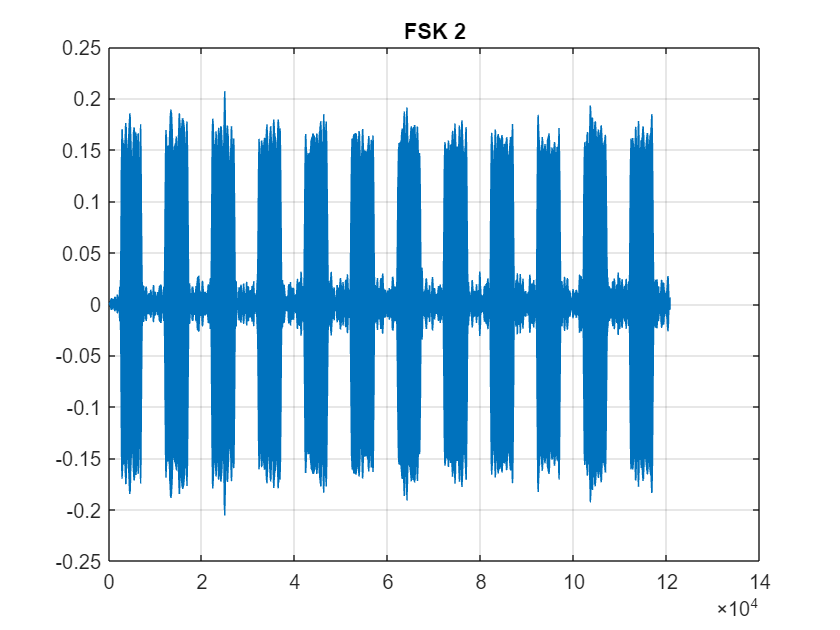

bpfilter = bpf2;                                    % BPF FIR Equiripple Filter built with Filter Designer
fsk2 = filter(bpfilter.Numerator, 1, (y_positive)); % Applying the BPF Filter to the signal
fsk2 = fsk2 / max(yR1);                             % Reduces the Amplitude
plot(fsk2)                                          % Generates a plot of fsk2
title('FSK 2')                                      % Sets the title for the plot
grid on;                                            % Generates a plot with grid lines

## **Step 22**

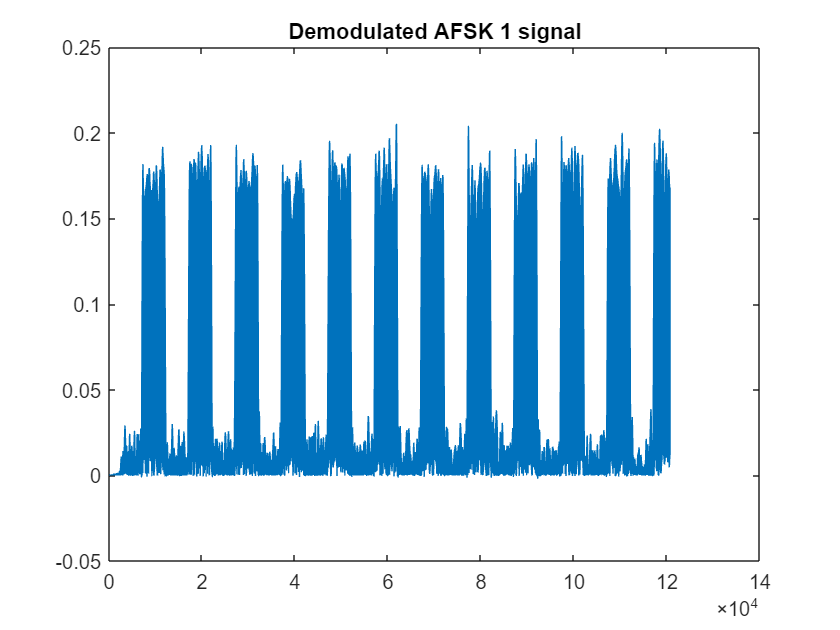

fsk1pos = abs(fsk1);                             % Calculates the Absolute Value of fsk1 and stores it in fsk1pos
lpfilter = lpf;                                  % LPF FIR Equiripple Filter built with Filter Designer
out1 = filter(lpfilter.Numerator, 1, (fsk1pos)); % Applying the LPF Filter to the signal
figure                                           % Creates a new figure window
plot(out1)                                       % Generates a plot of out1
title('Demodulated AFSK 1 signal')               % Sets the title for the plot

## **Step 23** 

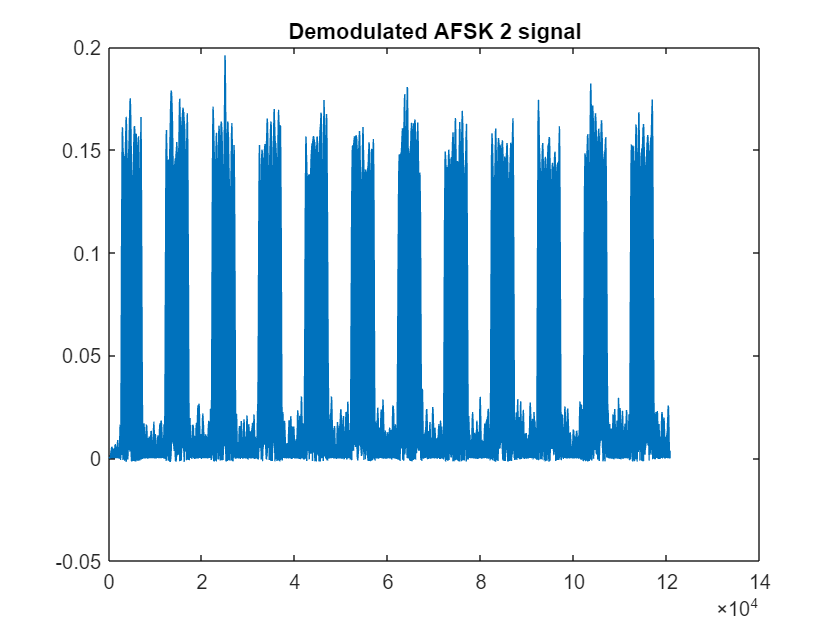

fsk2pos = abs(fsk2);                             % Calculates the Absolute Value of fsk2 and stores it in fsk2pos
lpfilter = lpf;                                  % LPF FIR Equiripple Filter built with Filter Designer
out2 = filter(lpfilter.Numerator, 1, (fsk2pos)); % Applying the LPF Filter to the signal
figure                                           % Creates a new figure window
plot(out2)                                       % Generates a plot of out2
title('Demodulated AFSK 2 signal')               % Sets the title for the plot